## Healthy Systemic Arteries Model

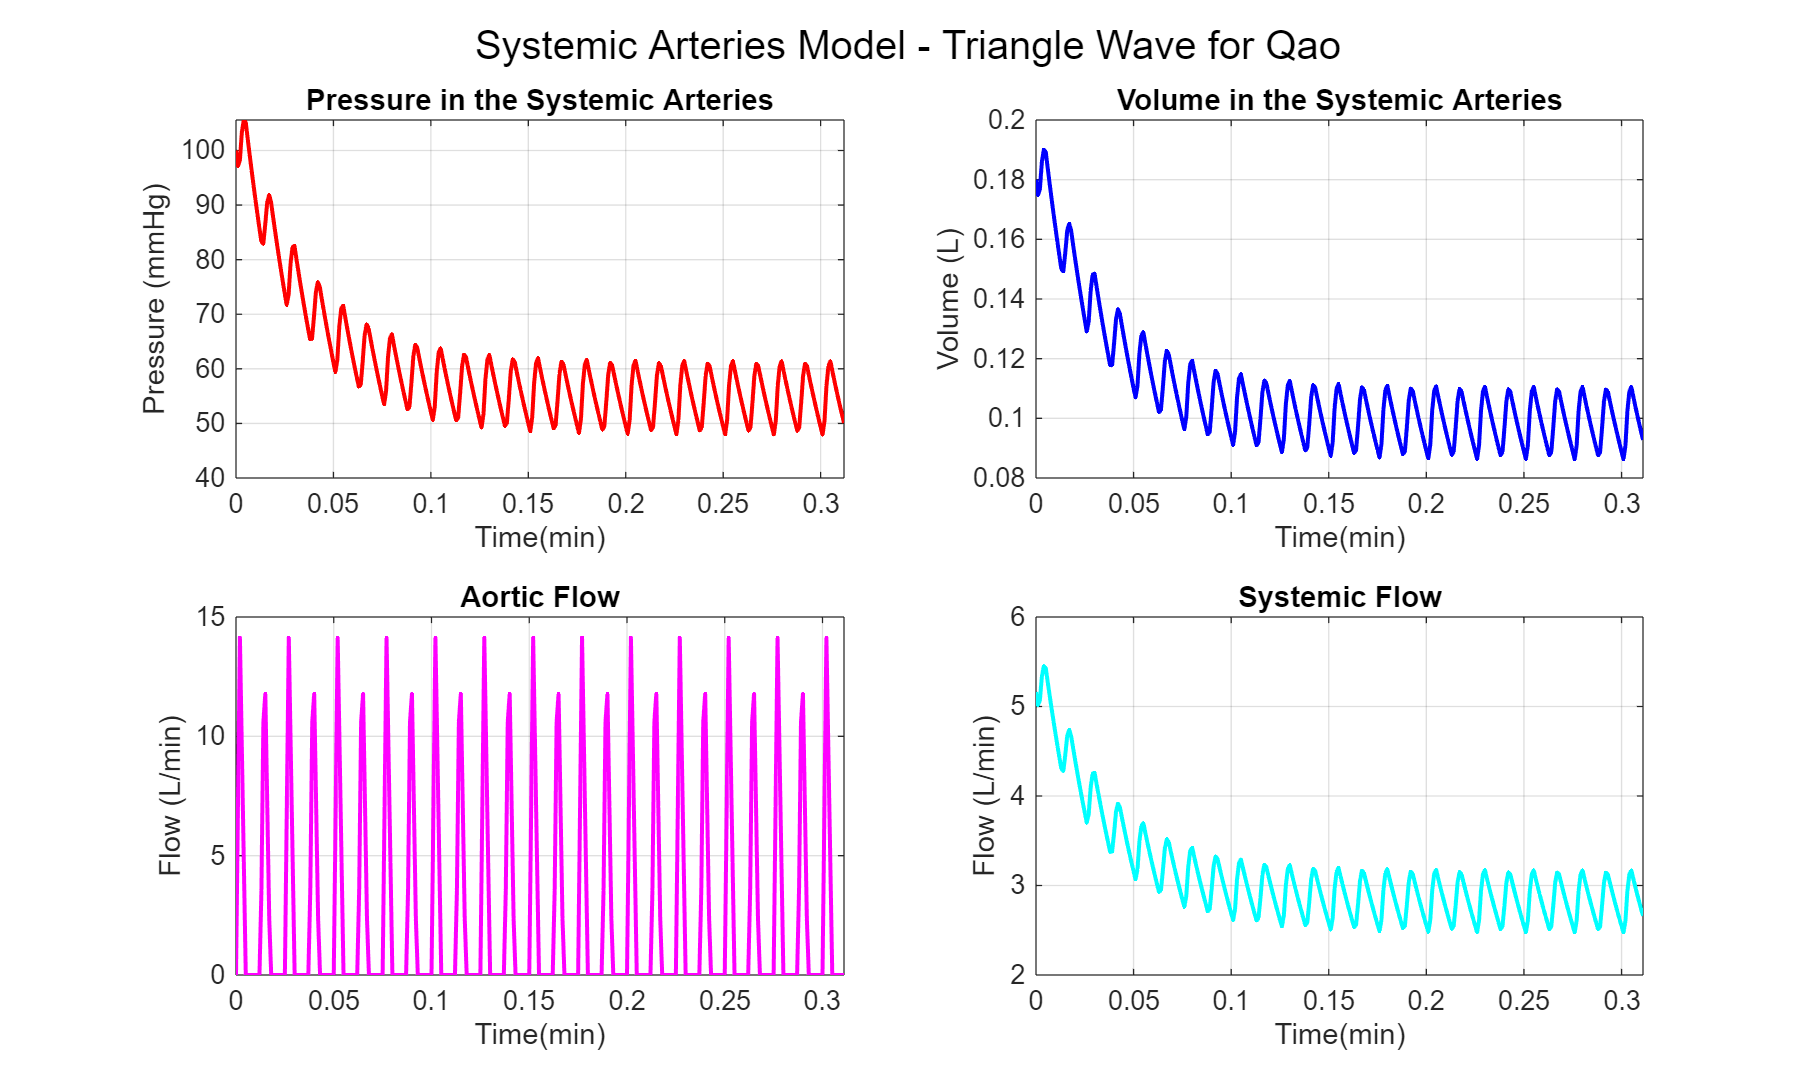

clear;clc;close all 
function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
% Csa & Rs were fiddled with to achieve Psa of 120/80 mmHg 

Psa=zeros(length(t),1); Psa(1)=100; % Pressure in systemic arteries (mmHg)
Vsa=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs(k)=Psa(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa(k+1)=Psa(k)+dt*(Qao(k)-Qs(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa(k)=Csa*Psa(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qao,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t(1:end-1),Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

## Question 1: The Aging Cardiovascular System 

- Background: Arteriosclerosis, or "hardening of the arteries," involves a reduction in arterial compliance. This decreased distensibility alters the relationship between blood volume and pressure in the arterial tree. 

- Task: Model arteriosclerosis by reducing the systemic arterial compliance parameter (C_sa) by a factor of 2 from your established baseline Systemic Arterial Model. Analyze and explain the resulting changes in systolic, diastolic, mean, and pulse pressures. 

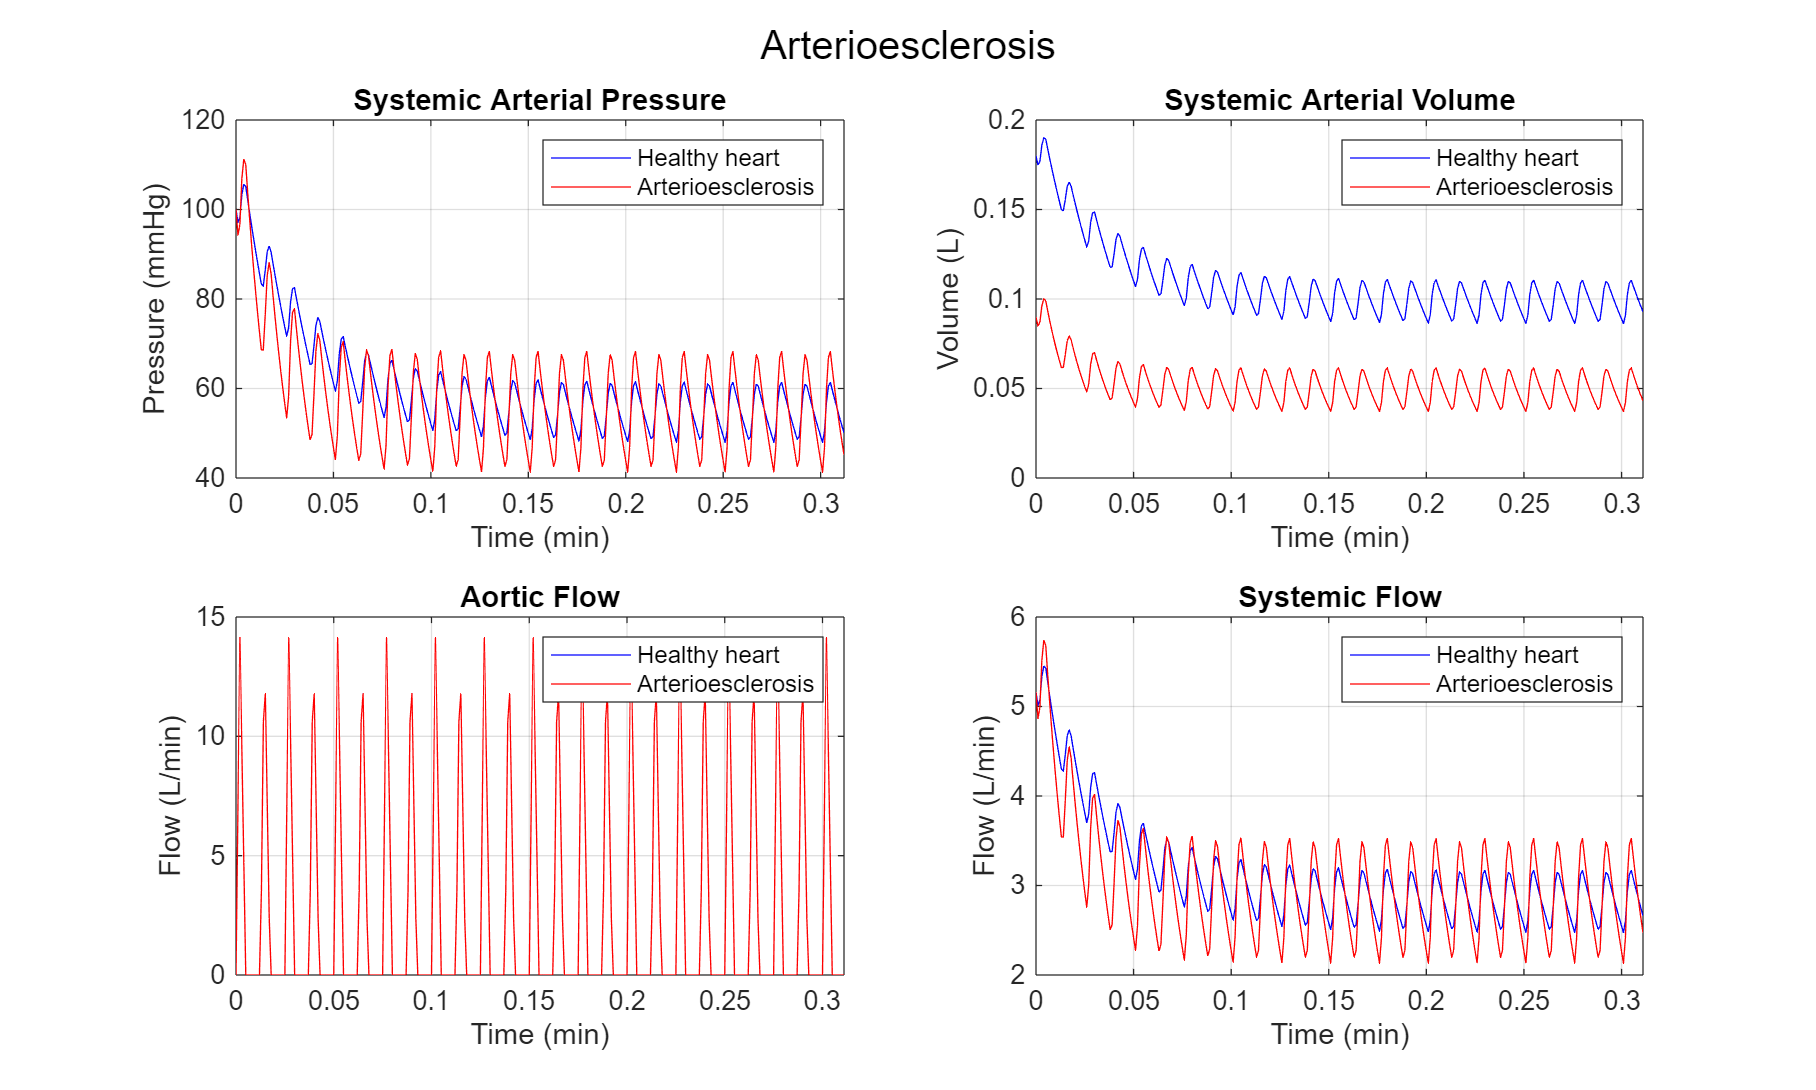

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
Csa_a = Csa/2; % Compliance constant for systemic arteries (L/mmHg) reduced by a factor of 2

Psa_a=zeros(length(t),1); Psa_a(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_a=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_a=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_a=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

for k=1:length(t)-1 
    Qao_a(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Aortic Flow 
    Qs_a(k)=Psa_a(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa_a(k+1)=Psa_a(k)+dt*(Qao_a(k)-Qs_a(k))/Csa_a;  % Pressure in Systemic Arteries 
    Vsa_a(k)=Csa_a*Psa_a(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Arterioesclerosis');
subplot(2,2,1);
plot(t,Psa,'b',t,Psa_a,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Healthy heart','Arterioesclerosis');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b',t(1:end-1),Vsa_a,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Healthy heart','Arterioesclerosis');

subplot(2,2,3);
plot(t(1:end-1),Qao,'b',t(1:end-1),Qao_a,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Healthy heart','Arterioesclerosis');

subplot(2,2,4);
plot(t(1:end-1),Qs,'b',t(1:end-1),Qs_a,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Healthy heart','Arterioesclerosis');

## Question 2: The Normal Hemodynamic Response to Exercise 

- Background: Exercise induces vasodilation in skeletal muscle by reducing systemic vascular resistance (R_s). To maintain blood pressure and increase delivery, cardiac output (CO) must rise, primarily through increased heart rate (HR). 

- Task: Simulate normal exercise using the Systemic Arterial Model. First, reduce R_s by a factor of 2. Then, double the heart rate by halving the cardiac cycle duration (T), systole duration (ts), and time to peak flow (tMAX). To maintain stroke volume (SV), you will need to adjust the peak aortic flow parameter (Qmax). Implement these changes and observe the new waveforms.

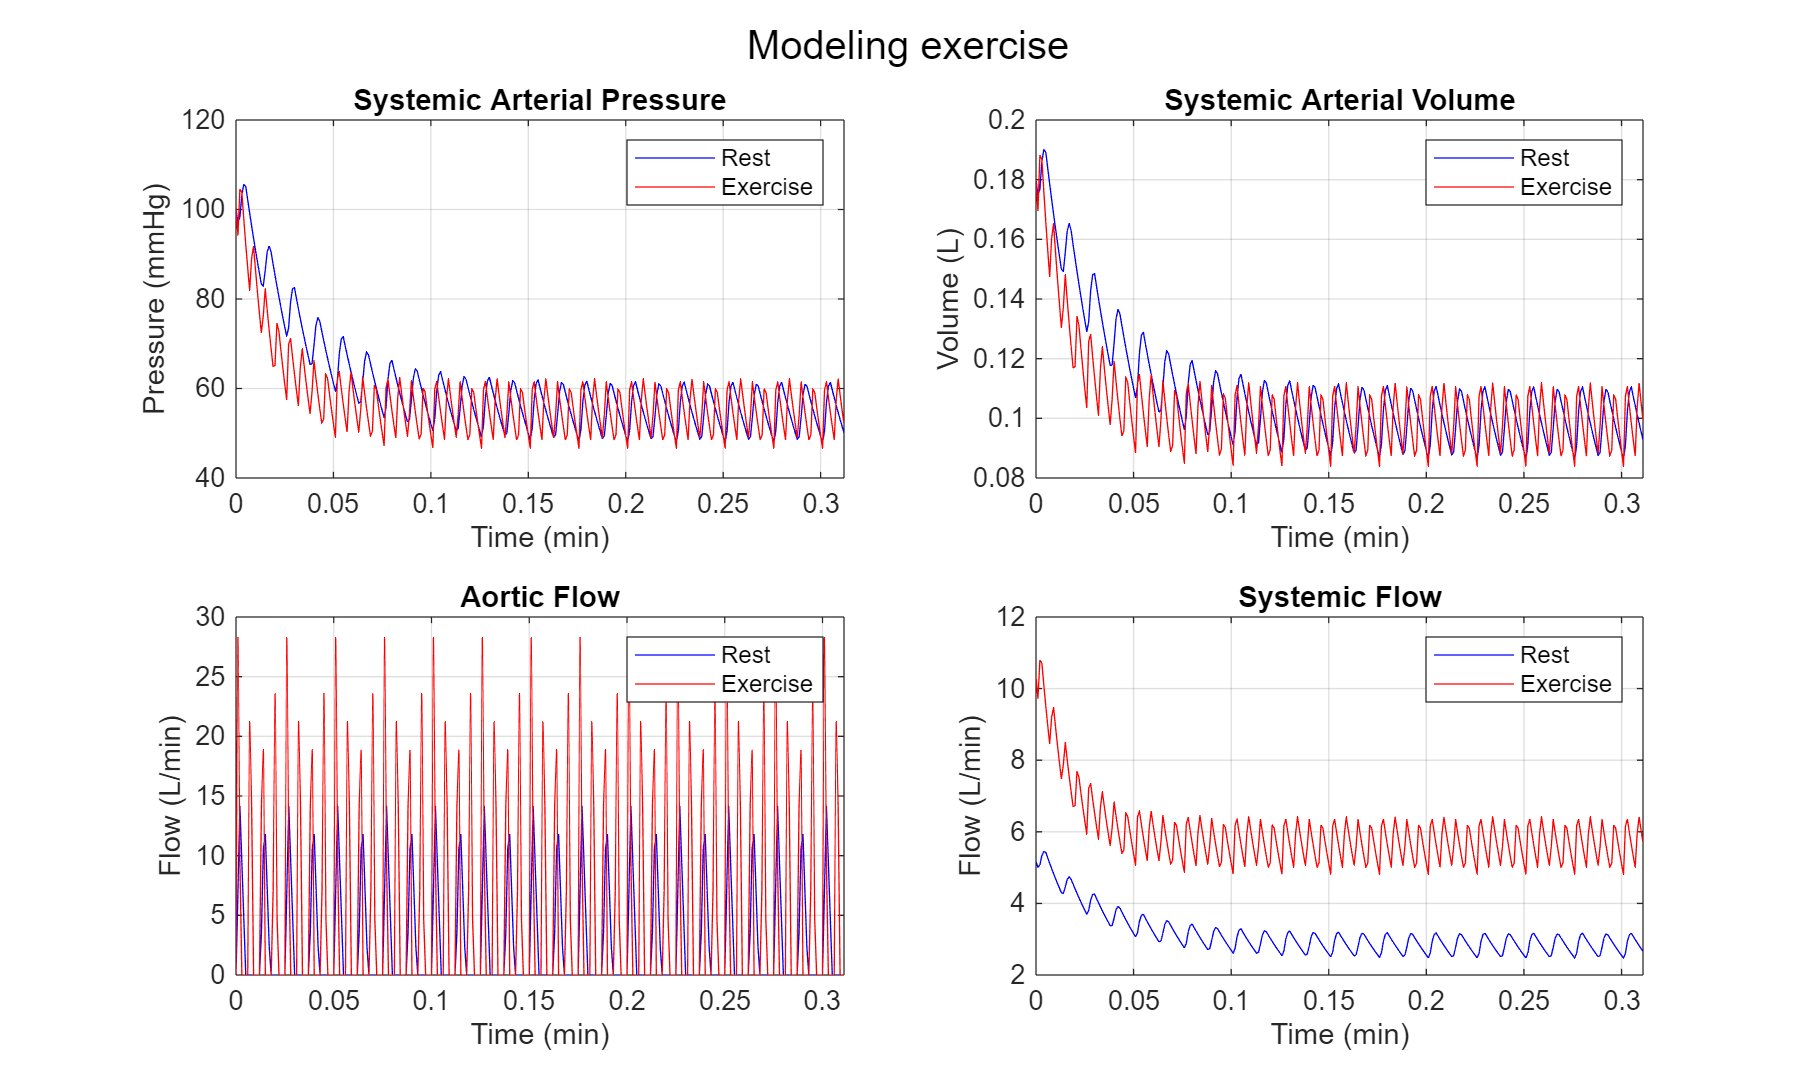

% Initial Parameters + Preallocating

T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 

% Exercise parameters
Rs_ex=Rs/2 ; % Resistance of the systemic circuit (mmHg/(L/min)) reduced by a factor of 2
T_ex=T/2;
ts_ex=ts/2;
tmax_ex=tmax/2;
Qmax_ex=2*Qmax;

Psa_ex=zeros(length(t),1); Psa_ex(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_ex=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_ex=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_ex=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% New hemodynamics
for k=1:length(t)-1 
    Qao_ex(k)=Qtriangwave(t(k),Qmax_ex,T_ex,ts_ex,tmax_ex);  % Aortic Flow 
    Qs_ex(k)=Psa_ex(k)/Rs_ex; % Systemic Flow, assuming Psv<<Psa
    Psa_ex(k+1)=Psa_ex(k)+dt*(Qao_ex(k)-Qs_ex(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_ex(k)=Csa*Psa_ex(k); % Volume in Systemic Arteries
end 

% Plotting
figure('Position',[100 100 1000 600]);
sgtitle('Modeling exercise');

subplot(2,2,1);
plot(t,Psa,'b',t,Psa_ex,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Rest','Exercise');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b',t(1:end-1),Vsa_ex,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Rest','Exercise');

subplot(2,2,3);
plot(t(1:end-1),Qao,'b',t(1:end-1),Qao_ex,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Rest','Exercise');

subplot(2,2,4);
plot(t(1:end-1),Qs,'b',t(1:end-1),Qs_ex,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Rest','Exercise');

## QUESTION 3: Exercise with an Abnormal Heart Rate Response

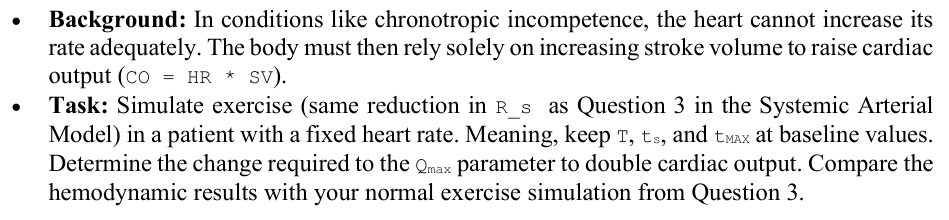

% Initial Parameters + Preallocating

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 

% Abnormal heart
Rs_ah = Rs/2; % Same reduction as Q2 
Qmax_ah=2*Qmax; % New Qmax to get double CO
 

Psa_ah=zeros(length(t),1); Psa_ah(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_ah=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_ah=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_ah=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% New hemodynamics 
for k=1:length(t)-1 
    Qao_ah(k)=Qtriangwave(t(k),Qmax_ah,T,ts,tmax);  % Aortic Flow 
    Qs_ah(k)=Psa_ah(k)/Rs_ah; % Systemic Flow, assuming Psv<<Psa
    Psa_ah(k+1)=Psa_ah(k)+dt*(Qao_ah(k)-Qs_ah(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_ah(k)=Csa*Psa_ah(k); % Volume in Systemic Arteries
end 

% Comparing results
CO_normal_r=mean(Qao)*80;
CO_normal_e=mean(Qao_ex)*80;
CO_abnormal=mean(Qao_ah)*80;
fprintf('CO for normal heart at rest = %.2f\nCO for normal heart during exercise = %.2f\nCO for abnormal exercise = %.2f',CO_normal_r,CO_normal_e,CO_abnormal);
figure('Position',[100 100 1000 600]);

CO for normal heart at rest = 226.60
CO for normal heart during exercise = 453.81
CO for abnormal exercise = 453.21

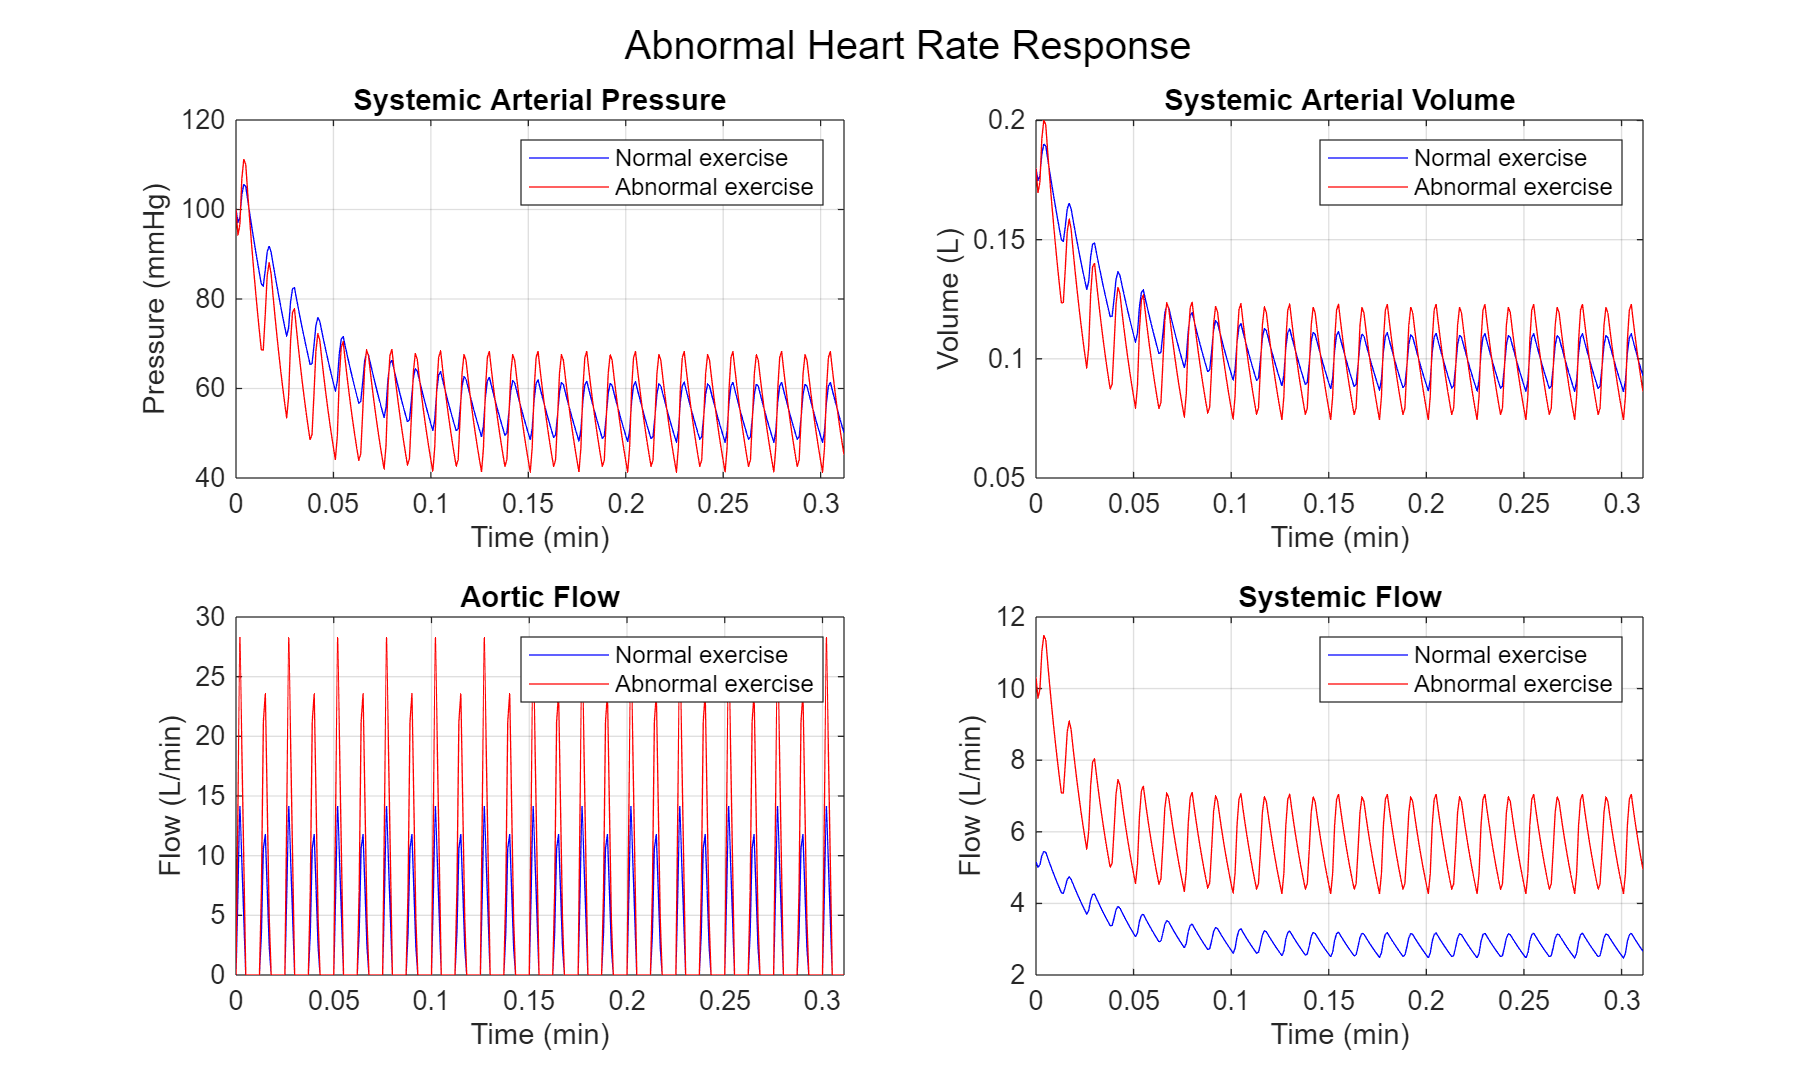

sgtitle('Abnormal Heart Rate Response');

subplot(2,2,1);
plot(t,Psa,'b',t,Psa_ah,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Normal exercise','Abnormal exercise');

subplot(2,2,2);
plot(t(1:end-1),Vsa,'b',t(1:end-1),Vsa_ah,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Normal exercise','Abnormal exercise');

subplot(2,2,3);
plot(t(1:end-1),Qao,'b',t(1:end-1),Qao_ah,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Normal exercise','Abnormal exercise');

subplot(2,2,4);
plot(t(1:end-1),Qs,'b',t(1:end-1),Qs_ah,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Normal exercise','Abnormal exercise');

## QUESTION 4: Tachycardia in the Absence of Metabolic Demand 

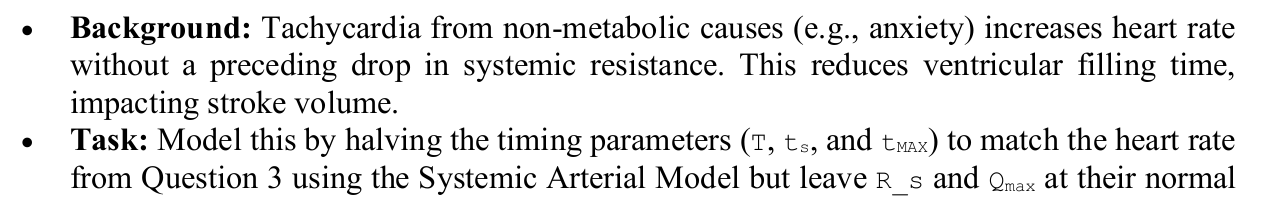

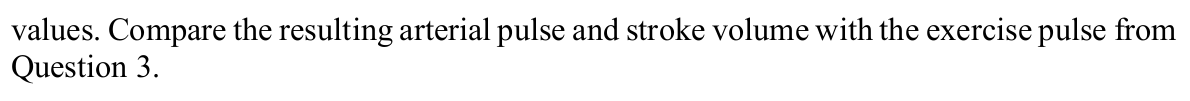

% Initial Parameters + Preallocating

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 

% Tachycardia (t values / 2)
T_t=T/2; 
ts_t=ts/2;
tmax_t=tmax/2;
 
Psa_t=zeros(length(t),1); Psa_t(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_t=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_t=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_t=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% New hemodynamics 
for k=1:length(t)-1 
    Qao_t(k)=Qtriangwave(t(k),Qmax,T_t,ts_t,tmax_t);  % Aortic Flow 
    Qs_t(k)=Psa_t(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa_t(k+1)=Psa_t(k)+dt*(Qao_t(k)-Qs_t(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_t(k)=Csa*Psa_t(k); % Volume in Systemic Arteries
end 

% Comparing results
% Stroke volume SV is the area under the curve for Qao, which is why we used trapz to calculate it
SV_normal_r=trapz(Qao)*60/1000; % L/min -> mL/s
SV_normal_e=trapz(Qao_ex)*60/1000;
SV_t=trapz(Qao_t)*60/1000;
fprintf('SV for normal heart at rest = %.2f\nSV for normal heart during exercise = %.2f\nSV for tachycardia = %.2f',SV_normal_r,SV_normal_e,SV_t);
figure
subplot(2,2,1);

SV for normal heart at rest = 53.02
SV for normal heart during exercise = 106.19
SV for tachycardia = 53.10

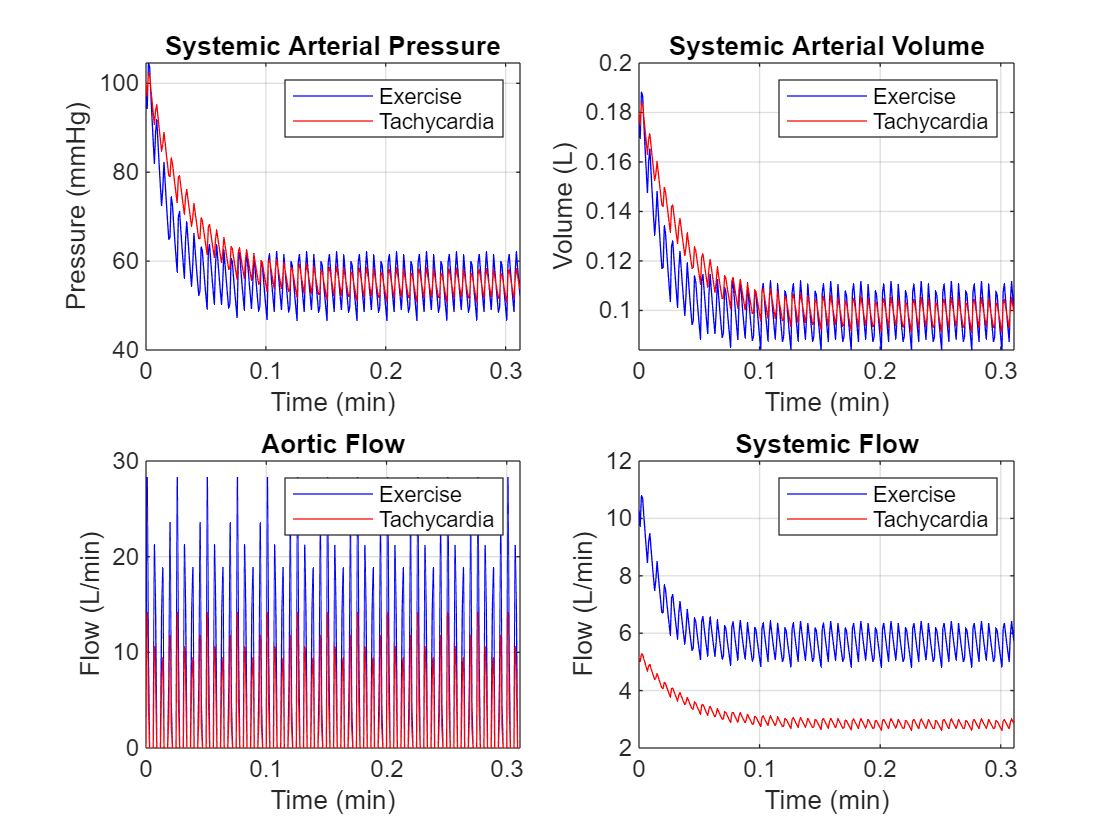

plot(t,Psa_ex,'b',t,Psa_t,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Exercise','Tachycardia');

subplot(2,2,2);
plot(t(1:end-1),Vsa_ex,'b',t(1:end-1),Vsa_t,'r');
xlabel('Time (min)'); 
ylabel('Volume (L)');
title('Systemic Arterial Volume'); 
grid on; 
legend('Exercise','Tachycardia');

subplot(2,2,3);
plot(t(1:end-1),Qao_ex,'b',t(1:end-1),Qao_t,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Aortic Flow'); 
grid on; 
legend('Exercise','Tachycardia');

subplot(2,2,4);
plot(t(1:end-1),Qs_ex,'b',t(1:end-1),Qs_t,'r');
xlabel('Time (min)'); 
ylabel('Flow (L/min)');
title('Systemic Flow'); 
grid on; 
legend('Exercise','Tachycardia');

## QUESTION 5: Modeling a Myocardial Infarction

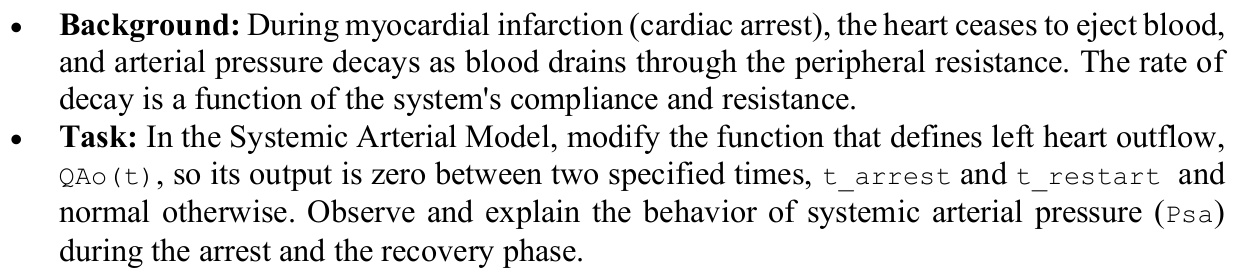

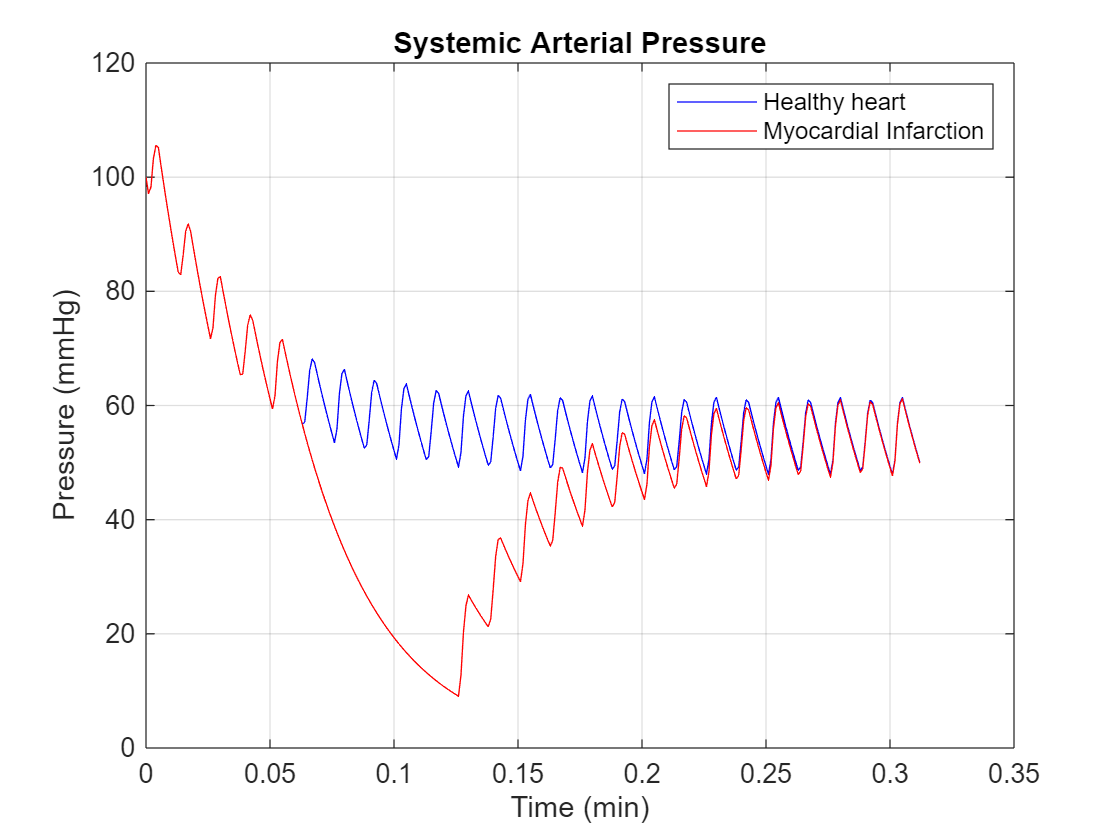

% New function for Qao
function Q=Qnew(t,Qmax,T,ts,tmax,t_arrest,t_restart)
    % Same function as before but Q=0 if t is between t_arrest and t_restart
    if t>=t_arrest && t<t_restart
                Q=0;
    else
        t1=rem(t,T);
            for ii=1:length(t)
                if t1(ii)<=ts 
                    if t1(ii)<=tmax 
                        Q(ii)=Qmax*t1(ii)/tmax;
                    else 
                        Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
                    end
                else 
                    Q(ii)=0;
                end
            end
    end 
end

% Baseline values
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
dt = 10e-4; % Time step (min)
t=0:dt:25*T;  % Vectorized time (min) 
Csa = 0.0015*1.2; % Compliance constant for systemic arteries (L/mmHg) 
Rs  = 17.5*1.107; % Resistance of the systemic circuit (mmHg/(L/min)) 
Qmax=14.14; % Max flow rate through aorta during systole (L/min) 
 
Psa_mi=zeros(length(t),1); Psa_mi(1)=100; % Pressure in systemic arteries (mmHg)
Vsa_mi=zeros(length(t)-1,1); % Volume in systemic arteries (L)
Qs_mi=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)
Qao_mi=zeros(length(t)-1,1); % Systemic Capillaries Flow (L/min)

% Assigning values to t_arrest & t_restart
t_arrest=5*T;
t_restart=10*T;

% New hemodynamics 
for k=1:length(t)-1 
    Qao_mi(k)=Qnew(t(k),Qmax,T,ts,tmax,t_arrest,t_restart);  % Aortic Flow 
    Qs_mi(k)=Psa_mi(k)/Rs; % Systemic Flow, assuming Psv<<Psa
    Psa_mi(k+1)=Psa_mi(k)+dt*(Qao_mi(k)-Qs_mi(k))/Csa;  % Pressure in Systemic Arteries 
    Vsa_mi(k)=Csa*Psa_mi(k); % Volume in Systemic Arteries
end 

% Comparing results
figure
plot(t,Psa,'b',t,Psa_mi,'r');
xlabel('Time (min)'); 
ylabel('Pressure (mmHg)');
title('Systemic Arterial Pressure'); 
grid on; 
legend('Healthy heart','Myocardial Infarction');